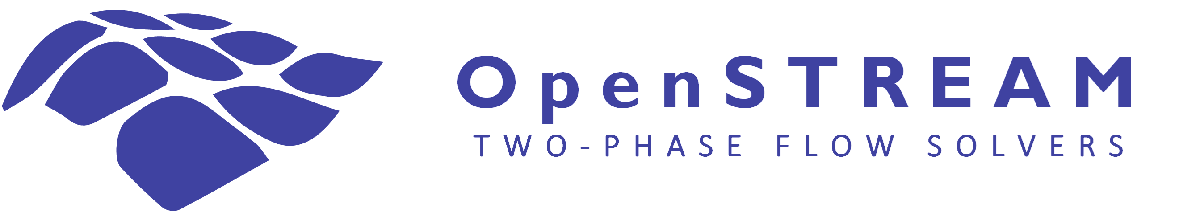

# Tutorial #1: Basic capabilities and functionalities

## Introduction

Welcome to OpenSTREAM!

In this tutorial, you will learn how to use the basic features of the code, with examples for all four solver types.

The geometry consist of a 3.5 m uniformly heated tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section. The flow enters slightly subcooled, transitions to annular two-phase flow around 0.7 m, and reaches film dryout at the end of the heated section. In the adiabatic region, droplets deposit on the wall, regenerating the liquid film at the wall and leading to a fully developed annular flow.

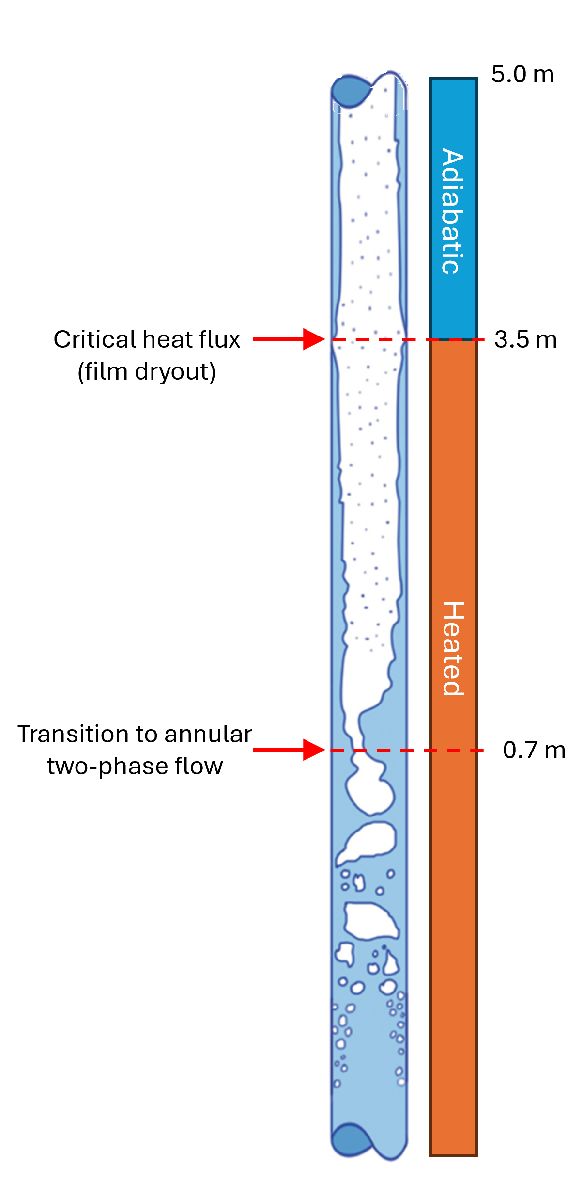git status

% Clear existing variables from workspace
clearvars

Before starting this tutorial, make sure OpenSTREAM is included in your MATLAB search path. If you are running the tutorial directly from the `tutorials` folder, you can add OpenSTREAM like this:

% Add path to OpenSTREAM
osp = './..';
addpath(osp);

## Input files

All the input files you will need for this tutorial are already provided in the `openstream/inputs/` folder.

We first start by adding the inputs and solver classes to the import list. 

% Import the necessary classes for inputs and solvers
import Inputs.*
import Solvers.*

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. Since each file can include various set of inputs (several geometries, etc.), the IDs corresponding to the relevant sets must be indicated. These paths can be modified by the user, based on the specific working directory and file locations.

The models and options parameters not specified in the input files are set to their default values. Turning on the warning will print the corresponding selected values to the prompt. 

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSet = InputSet( ...
            modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL1', ...
            optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
            geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
            bcFilePath            = [osp '/inputs/tutorial1.inp'], ...
            sessionParentDir      = fullfile(pwd,'outputs')    , ...
            overwriteSessionFiles = true                       , ...
            LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

Note that `LOGMODE` can be set to `'LOGTOFILEONLY'` to suppress (almost) all print outputs when running OpenSTREAM.

We can examine the physical model inputs by opening the models file or using the command below, then scroll to locate the entry labeled `TUTORIAL1`.

type('../inputs/models.inp')


ID            ! Models ID                                                  > TUTORIAL1
NNODES        ! Number of axial nodes                                      > 100
FLUID         ! Fluid ID                                                   > WATER
INTNU         ! Interfacial heat transfer model                            > RELAXATION
RELAXX        ! Condensation relaxation time [s]                           > -0.5 1.0
RELAXTCOND    ! Condensation relaxation time [s]                           >  0.5 0.5 0.01
MOMENTLIQUID  ! Liquid momentum conservation model                         > FULL
MOMENTGAS     ! Gas momentum conservation model                            > FULL
MOMENTFILM    ! Film momentum conservation model                           > FULL
MOMENTDROP    ! Drop momentum conservation model                           > FULL
WAVEBASEINT   ! Wave / base film interfacial momentum transfer model       > VAPORSHEARDROPMASS
OAFFILMSPLIT  ! Film mass flow split model at onset of annu

This indicates that the simulations will use 100 nodes and that water is the working fluid. Additional model inputs are solver-specific.

A simple and self-explanatory input file format has been defined for use with OpenSTREAM, as shown above. Alternatively, a JSON file format can also be used if preferred.

type('../inputs/models.json')


[
  {
    "ID": "TUTORIAL1",
    "NNODES": 100,
    "FLUID": "WATER",
    "INTNU": "RELAXATION",
    "RELAXX": [
      -0.5,
      1.0
    ],
    "RELAXTCOND": [
      0.5,
      0.5,
      0.01
    ],
    "MOMENTLIQUID": "FULL",
    "MOMENTGAS": "FULL",
    "MOMENTFILM": "FULL",
    "MOMENTDROP": "FULL",
    "WAVEBASEINT": "VAPORSHEARDROPMASS",
    "OAFFILMSPLIT": "RATIO",
    "OAFBASERATIO": 0.2,
    "BASEEQTHICK": "YPLUS"
  }
]


We can examine the numerical option inputs by opening the options file or using the command below, then scroll to locate the entry labeled `DEFAULT`.

type('../inputs/options.inp')


ID            ! Options ID                                                 > DEFAULT
END


Note that no specific options have been defined, i.e., defaults setting are used for the simulations.

We can examine the geometry inputs by opening the geometry file or using the command below, then scroll to locate the entry labeled `TUTORIAL1`.

type('../inputs/geom.inp')


ID        ! Channel ID                     > TUTORIAL1
LENGTH    ! Axial length [m]               > 5.5
AREA      ! Coolant area [m^2]             > 6.0821e-05
PERIM     ! Perimeters [m]                 > 0.0276
ANGLE     ! Angle [rad]                    > 0
END


All inputs are required except for `ANGLE`, which defaults to 0, indicating a vertical test section. The separate specification of `AREA` and `PERIM` allows to define test sections of arbitrary shape. In this case, the area and perimeter corresponding to a circular test section with a diameter 8.8 mm were specified.

Finally, we can examine the boundary conditions by opening the boundary conditions file or using the command below.

type('../inputs/tutorial1.inp')


TIME          ! Time [s]                                                   > 0.0
PRESSURE      ! System pressure [Pa]                                       > 6000000
HIN           ! Inlet enthalpy [J/kg]                                      > 1.1394E6
MFLOW         ! Mass flow rate [kg/s]                                      > 0.07
POWER         ! Total power [W]                                            > 87500
WMESH         ! Relative power node size distribution [m]                  > 3.5 2.0 
WPOWER        ! Relative power distribution(s) [-]                         > 1.0 0.0
END




Defining a single time step indicates that the simulation is steady-state. The axial power distribution is specified using two arrays: `WMESH` for node size and `WPOWER` for corresponding wall heat flux. In this case, the configuration represents a 3.5 m uniformly heated section followed by a 2 m adiabatic section.

All inputs are required except for `WMESH` and `WPOWER`. If they are omitted, the test section is assumed to be uniformly heated by default.

## Mixture solver

In this section, we will walk through how to set up and run the mixture solver using a simple example.

The physical models specified in the input file do not affect the solver’s default settings for this solver, which in this case reduce to a Homogeneous Equilibrium Model (HEM).

We first start by adding the mixture solver classes to the import list. 

% Import the mixture solver class
import Solvers.Mixture.*

A mixture solver object, `mixSolver`, is created from the `inputSet`.

% Create the mixture solver object
mixSolver = MixtureSolver(inputSet);

While the mixture solver object is initialized at construction. Here, it is explicitly initialized for clarity.

% Initialize solver
mixSolver.initializeSolver(); 

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolver.solve();



--------------------------------------------- Mixture solver run initiated ---------------------------------------------

Solve steady-state ...
Time  1.00 [s]	max point iter =   5 in node   6, max errors: W = 0.0000001 [kg/s], P = 0.07547 [Pa], H = 0.08701 [J/kg]                    
Time  2.00 [s]	max point iter =   4 in node   5, max errors: W = 0.0000014 [kg/s], P = 0.09865 [Pa], H = 0.05141 [J/kg]                    
Time  3.00 [s]	max point iter =   4 in node  80, max errors: W = 0.0000002 [kg/s], P = 0.09691 [Pa], H = 0.06371 [J/kg]                    
Time  4.00 [s]	max point iter =   3 in node   5, max errors: W = 0.0000000 [kg/s], P = 0.00273 [Pa], H = 0.00318 [J/kg]                    
Time  5.00 [s]	max point iter =   3 in node   7, max errors: W = 0.0000000 [kg/s], P = 0.09601 [Pa], H = 0.02859 [J/kg]                    
Time  6.00 [s]	max point iter =   3 in node  14, max errors: W = 0.0000001 [kg/s], P = 0.08306 [Pa], H = 0.09930 [J/kg]                    
Time  7.00 [s

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If convergence is reached, it prints a summary of the time step convergence.

We can now look at the code outputs. For instance, the solved void fraction array can be printed from the mixture property

% Display the void fraction
disp(mixSolver.mixture.VF')

         0         0         0         0    0.0707    0.2820    0.4178    0.5124    0.5822    0.6357    0.6781    0.7124    0.7409    0.7648    0.7852    0.8028    0.8182    0.8317    0.8437    0.8544    0.8639    0.8726    0.8805    0.8876    0.8942    0.9002    0.9058    0.9109    0.9157    0.9201    0.9242    0.9281    0.9317    0.9351    0.9383    0.9413    0.9441    0.9468    0.9494    0.9518    0.9541    0.9562    0.9583    0.9603    0.9622    0.9640    0.9657    0.9673    0.9689    0.9704    0.9719    0.9733    0.9746    0.9759    0.9771    0.9783    0.9795    0.9806    0.9817    0.9827    0.9837    0.9847    0.9856    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865

The mixture solver class includes built-in plotting functions to help visualize the results. Here are a few examples you can try:

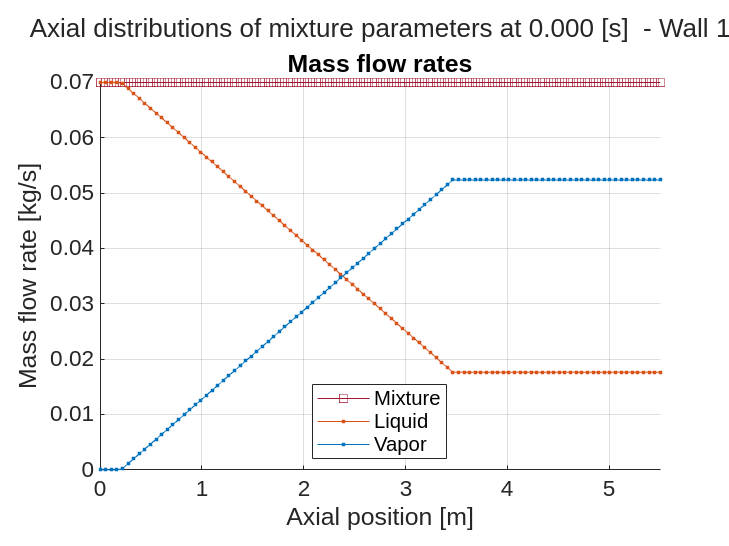

% Plot the axial distribution of mass flow rates
mixSolver.plotz('display','W');

Vapor generation begins near the inlet of the test section as the mixture reaches saturation. From there, vapor mass increases  linearly along the heated length due to the uniform heat flux, and then remains constant throughout the adiabatic section.

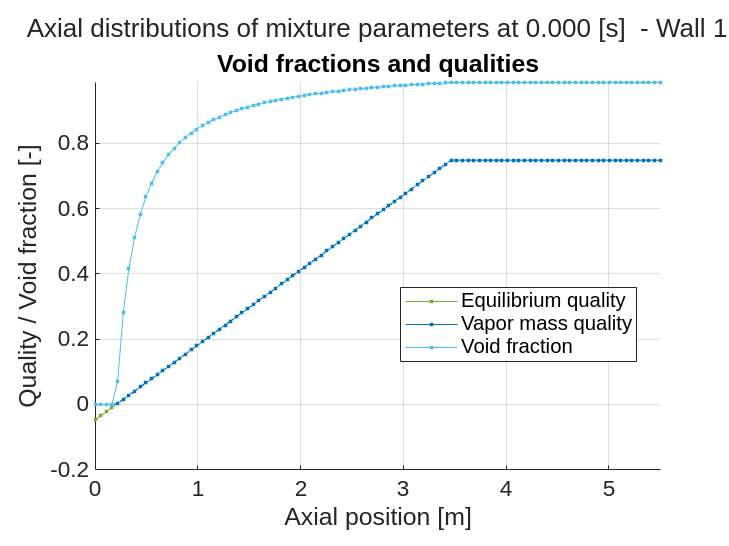

% Plot the axial distribution of vapor ratios
mixSolver.plotz('display','VR');

The figure confirms that the mixture becomes saturated (xeq ≥ 0) as the steam mass (and void fraction) starts increasing

Results can be saved if desired.

% Save results
mixSolver.save('name','mixSolver','showpath',false);

## Two-fluid solver

In this section, we will walk through how to set up and run the two-fluid solver using a simple example.

The physical models specified in the input file modify the phase velocity calculation model by a applying a full momentum conservation model (`MOMENTGAS` and `MOMENTLIQUID` set to `FULL`). In addition, the interfacial transfer model is simplified by a applying a time relaxation approach (`INTNU` set to `RELAXATION`).

We first start by adding the two-fluid solver class to the import list. 

% Import the two-fluid solver class
import Solvers.TwoFluid.*

Since the input parameters are already loaded, we can reuse the same input set without re-reading the files.

We create a two-fluid solver object, `twfSolver`, using the `inputSet` and the previously solved mixture solver. This lets the two-fluid solver start from a physically reasonable state and inherit the pressure gradient already computed by the mixture solver.

% Create the two-fluid solver object
twfSolver = TwoFluidSolver(inputSet, mixSolver);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
twfSolver.solve();



-------------------------------------------- Two-fluid solver run initiated --------------------------------------------

Solve steady-state ...
Time  1.00 [s]	max point iter =  37 in node  14, max errors: Wl = 0.0000000 [kg/s], Wv = 0.0000001 [kg/s], Ul = 0.0000999 [m/s], Uv = 0.0000911 [m/s], Hl = 0.08613 [J/kg], Hv = 0.00000 [J/kg]                    
Time  2.00 [s]	max point iter =  28 in node  14, max errors: Wl = 0.0000002 [kg/s], Wv = 0.0000001 [kg/s], Ul = 0.0000994 [m/s], Uv = 0.0000961 [m/s], Hl = 0.04708 [J/kg], Hv = 0.00000 [J/kg]                    
Time  3.00 [s]	max point iter =  19 in node  14, max errors: Wl = 0.0000001 [kg/s], Wv = 0.0000001 [kg/s], Ul = 0.0000988 [m/s], Uv = 0.0000963 [m/s], Hl = 0.08815 [J/kg], Hv = 0.00000 [J/kg]                    
Time  4.00 [s]	max point iter =  10 in node  65, max errors: Wl = 0.0000000 [kg/s], Wv = 0.0000001 [kg/s], Ul = 0.0000987 [m/s], Uv = 0.0000981 [m/s], Hl = 0.07355 [J/kg], Hv = 0.00000 [J/kg]                    
Time 

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for phase mass flow rates, velocities, and enthalpies. It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If convergence is reached, it prints a summary of the time step convergence.

The two-fluid solver class includes built-in plotting functions to help visualize the results. Here are a few examples you can try:

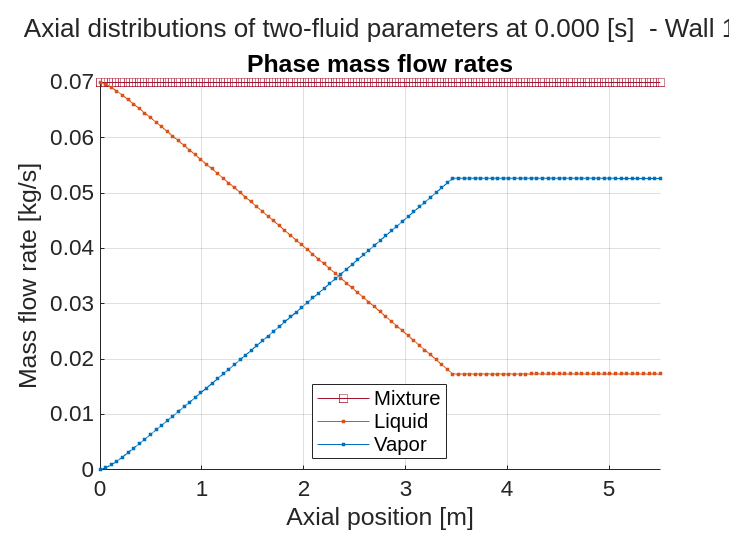

% Plot the axial distribution of mass flow rates
twfSolver.plotz('display','W');

The solution is the same to what the mixture solver provides, but with one key difference: vapor generation starts further upstream in the subcooled region due to wall boiling.

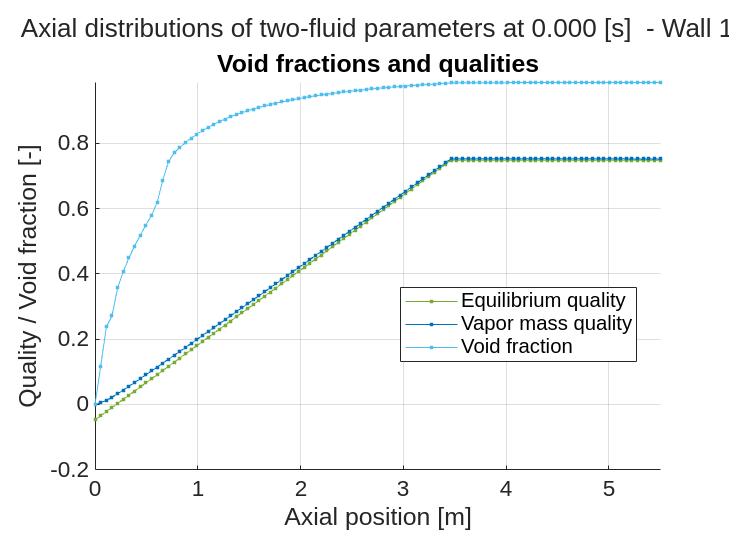

% Plot the axial distribution of vapor ratios
twfSolver.plotz('display','VR');

The observation from the previous plot is confirmed. Near the inlet of the test section, the vapor mass quality begins to increase even though the thermodynamic equilibrium quality is still negative, characteristic of subcooled boiling.

Results can be saved if desired.

% Save results
twfSolver.save('name','twfSolver','showpath',false);

## Three-field solver

In this section, we will walk through how to set up and run the three-field solver using a simple example.

The physical models specified in the input file modify the drop velocity calculation model by a applying a full momentum conservation model (`MOMENTDROP` set to `FULL`).

We first start by adding the three-field solver class to the import list. 

% Import the three-field solver class
import Solvers.ThreeField.*

Since the input parameters are already loaded, we can reuse the same input set without re-reading the files.

We create a three-field solver object, `tfSolver`, using `inputSet` and the previously solved mixture solver. This lets the three-field solver start from a physically reasonable state and inherit the pressure gradient already computed by the mixture solver.

% Create the three-field solver object
tfSolver = ThreeFieldSolver(inputSet, mixSolver);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
tfSolver.solve();



------------------------------------------- Three-field solver run initiated -------------------------------------------

Solve steady-state ...
Time  1.00 [s]	max point iter =  16 in node  63, max errors: Wf = 0.0000985 [kg/s/m], Uf = 0.00629 [m/s], Ud = 0.00999 [m/s]                    
Time  2.00 [s]	max point iter =   8 in node  18, max errors: Wf = 0.0000986 [kg/s/m], Uf = 0.00020 [m/s], Ud = 0.00950 [m/s]                    
Time  3.00 [s]	max point iter =   5 in node  24, max errors: Wf = 0.0000981 [kg/s/m], Uf = 0.00010 [m/s], Ud = 0.00769 [m/s]                    
Time  4.00 [s]	max point iter =   2 in node  23, max errors: Wf = 0.0000975 [kg/s/m], Uf = 0.00007 [m/s], Ud = 0.00725 [m/s]                    
Time  5.00 [s]	max point iter =   1 in node   2, max errors: Wf = 0.0000843 [kg/s/m], Uf = 0.00007 [m/s], Ud = 0.00681 [m/s]                    
		STEADY-STATE CONVERGED            max errors: Wf = 0.0000843 [kg/s/m], Uf = 0.00007 [m/s], Ud = 0.00681 [m/s]
Elapsed time: 3.

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for liquid film mass flow rate, liquid film velocity, and droplet velocity.  It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If convergence is reached, it prints a summary of the time step convergence.

The three-field solver class includes built-in plotting functions to help visualize the results. Here are a few examples you can try:

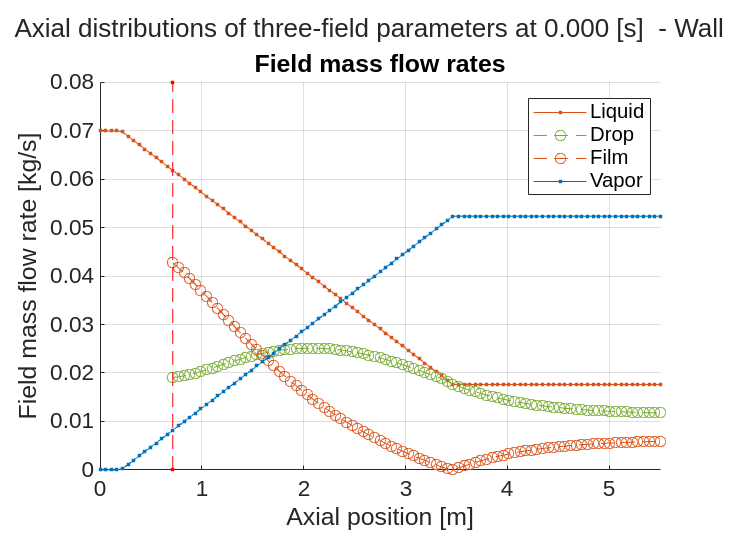

% Plot the axial distribution of mass flow rates
tfSolver.plotz('display','W');

The three-field solution is shown only downstream the onset of annular flow conditions.

The solution is the same to what the mixture solver provides, but with one key difference: the liquid mass flow rate is split into film and droplets.

As mentioned in the case description, the liquid film mass flow rate is observed to reduce to 0 at the end of heated section (3.5 m). Further downstream, the film is gradually regenerated as droplet deposit onto the wall along the adiabatic section.

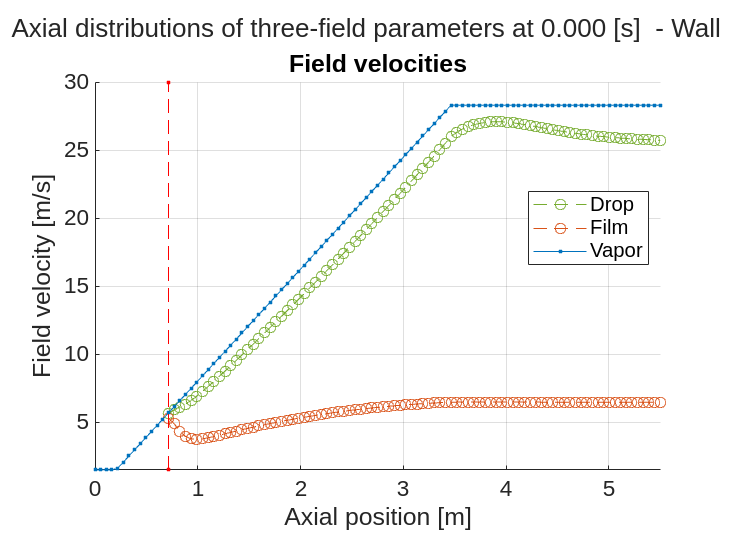

% Plot the axial distribution of velocities
tfSolver.plotz('display','U');

As expected, the film velocity insignificantly lower than the droplet velocity. The droplet velocity is slightly lower than the vapor velocity.

Results can be saved if desired.

% Save results
tfSolver.save('name','tfSolver','showpath',false);

## Four-field solver

In this section, we will walk through how to set up and run the four-field solver using a simple example.

The physical models specified in the input file modify several default settings related to base film/wave mass exchange, film/wave distribution at the onset of annular flow, and interfacial momentum exchange for the base film. These parameters are covered in more detail in advanced tutorials dedicated to the four-field solver.

We first start by adding the four-field solver class to the import list. 

% Import the four-field solver class
import Solvers.FourField.*

The input parameters are unchanged, hence the input set does not need to be read again.

We create a four-field solver object, `ffSolver`, using `inputSet` and the previously solved mixture solver. This lets the four-field solver start from a physically reasonable state and inherit the pressure gradient already computed by the mixture solver.

% Create the four-field solver object
ffSolver = FourFieldSolver(inputSet, mixSolver);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
ffSolver.solve();



------------------------------------------- Four-field solver run initiated --------------------------------------------

Solve steady-state ...
Time  1.00 [s]	max point iter = 100 in node  14, max errors: Wb = 0.0007327 [kg/s/m], Ub = 0.67180 [m/s], Ww = 0.0005019 [kg/s/m], Uw = 0.00981 [m/s], Fw = 0.00649 [Hz], Ud = 0.00998 [m/s]                    
Time  2.00 [s]	max point iter = 100 in node  12, max errors: Wb = 0.0014390 [kg/s/m], Ub = 0.76035 [m/s], Ww = 0.0009916 [kg/s/m], Uw = 0.00578 [m/s], Fw = 0.09903 [Hz], Ud = 0.00964 [m/s]                    
Time  3.00 [s]	max point iter = 100 in node  14, max errors: Wb = 0.0008920 [kg/s/m], Ub = 0.74878 [m/s], Ww = 0.0006128 [kg/s/m], Uw = 0.00440 [m/s], Fw = 0.09970 [Hz], Ud = 0.00777 [m/s]                    
Time  4.00 [s]	max point iter = 100 in node  14, max errors: Wb = 0.0008376 [kg/s/m], Ub = 0.73718 [m/s], Ww = 0.0005745 [kg/s/m], Uw = 0.00372 [m/s], Fw = 0.09320 [Hz], Ud = 0.00728 [m/s]                    
Time  5.00 [s]	ma

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for liquid base film mass flow rate and velocity, wave mass flow rate and velocity, and drop velocity. It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If convergence is reached, it prints a summary of the time step convergence.

The four-field solver class includes built-in plotting functions to help visualize the results. Here are a few examples you can try:

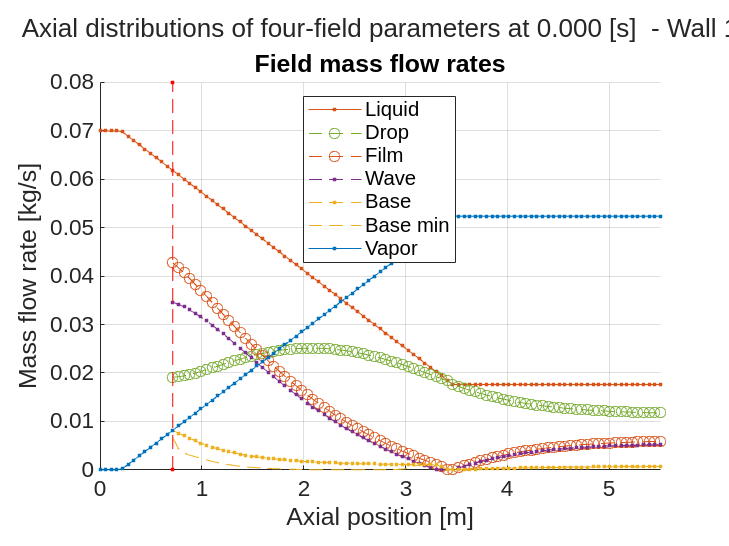

% Plot the axial distribution of mass flow rates
ffSolver.plotz('display','W');

The solution is the same to what the three-field solver provides, but with one key difference: the liquid film mass flow rate is split into base film and disturbance waves. Away from the film dryout region, it can be observed that most the the film mass is transported by the waves.

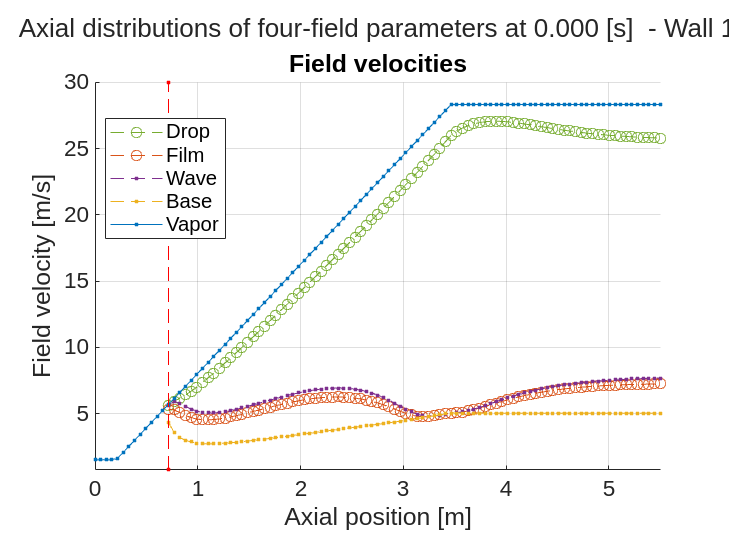

% Plot the axial distribution of velocities
ffSolver.plotz('display','U');

As expected, the disturbance wave velocity is higher than the base film velocity, except near film dryout. The droplet velocity is slightly lower than the vapor velocity.

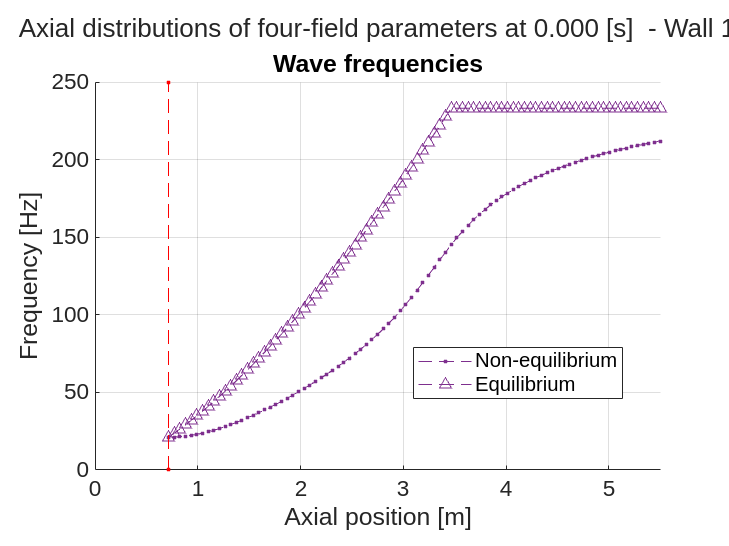

% Plot the axial distribution of wave frequency
ffSolver.plotz('display','FREQUENCY');

The figure shows the predicted disturbance wave frequency, alongside the result from the reference equilibrium model. As expected, the wave frequency initially lags behind its equilibrium value and gradually approaches it along the adiabatic section.

Results can be saved if desired.

% Save results
ffSolver.save('name','ffSolver','showpath',false);